# ***Misfit_Roughness_grid.mlx***

Το script αυτό αφορά στην περίπτωση επιλογής σταθμών GPS διατεταγμένων σε πλέγμα (grid). Αποτελεί παραλλαγή του 'Misfit_Roughness.mlx'. Aναπτύχθηκε στην προσπάθεια προσδιορισμού του ιδανικού συντελεστή λείανσης *k* της Αντιστροφής των συνθετικών δεδομένων (ξεχωριστές περιπτώσεις για μικρό – μεγάλο σφάλμα στο αρχείο input data). Πραγματοποιεί την Αντιστροφή των συνθετικών δεδομένων για δοθέντες τιμές του συντελεστή λείανσης *k* (μεταβλητή *SF* στο script), υπολογίζει τις τιμές Roughness και Misfit για κάθε Inversion, και σχεδιάζει την L-curve. Επιλέγεται ως ιδανικό *k* το γόνατο της L-curve, το οποίο προσδιορίζεται ως το σημείο της με τη μέγιστη απόσταση από το ευθύγραμμο τμήμα SF (Start-Finish -- να μην συγχέεται με τη μεταβλητή *SF *του script).

Αρχικά θέτουμε ως θέση που τρέχει η Matlab το εσωτερικό του φακέλου 'Project'. Όπου υπάρχει σε σχόλιο το "-->", η μεταβλητή πρέπει να εισαχθεί από το χρήστη ανάλογα με τα δεδομένα του προβλήματος.

Για να τρέξει το συγκεκριμένο script θα πρέπει να έχει προηγουμένως τρέξει το script ‘forward_modeling_grid.mlx’, ώστε να έχει αποθηκευτεί το αντίστοιχο Workspace (‘Workspace_ForwardModeling_grid.mat’).

# Inversion of Synthetic Data (Low Error)

% Copyright (c) 2018, Livadas – Stathakopoulos Ioannis (yiannislibad@hotmail.gr)
% Covered by MIT Licence
% Πραγματοποιείται εντός αναφορά σχετικά με χρήση scripts ή λογισμικού τρίτων.

% Επιτρέπουμε στη Matlab να έχει πρόσβαση στα περιεχόμενα του φακέλου Project.
folder = fileparts(which('Misfit_Roughness_grid.mlx'));
addpath(genpath(folder));
clearvars

% Φόρτωση του Workspace που αποθηκεύτηκε από το 'Forward_Modeling.mlx'
load Workspace_ForwardModeling_grid.mat

## Εισαγωγή Δεδομένων

Δίνουμε τις παρακάτω μεταβλητές του ρήγματος:

PR = 0.25;                % --> Poisson ratio (default = 0.25, όμοιο με FM)
PS = 1.0;                 % --> Patch size [km]
mR = 0; MR = 360;         % --> min-Max Rake [deg] (a-priori)
MS = 50.0;                % --> Max Slip [m] (a-priori)  
tD_A = Dip; bD_A = Dip;   % top-bottom Dip of point A (fault trace) [deg]
tD_B = Dip; bD_B = Dip;   % top-bottom Dip of point B (fault trace) [deg]
CN = 10000;               % --> Αριθμός κύκλων

Καθορίζουμε τις τιμές του συντελεστή k:

SF_values = [0.012 0.015 0.02 0.03 0.05, 0.06, 0.07, 0.08, 0.1, 0.12, 0.15, 0.18, 0.23, 0.30, 0.35, 0.40,...
    0.45, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 1.25, 1.5, 2];  % --> Οι τιμές του συντ. k

SF_values_names = num2str((SF_values'));

## Σύνθεση αρχείων input data

Συντάσσονται τα αρχεία input data για τρεις διευθύνσεις (North, East, Z), τα οποία αποθηκεύονται εντός του υποφακέλου 'GPS_Synthetic_Grid'.

% Μορφολογία σύνταξης των αρχείων input data (για κάθε διεύθυνυση...
    % [lat lon slip error])
dispacement_North = [coordinates_grid_trans 1000*uNgrid_trans ...
    1000*repmat(sigma_uN,points_E*points_N,1)];
displacement_East = [coordinates_grid_trans 1000*uEgrid_trans ...
    1000*repmat(sigma_uE,points_E*points_N,1)];
displacement_Up = [coordinates_grid_trans 1000*uZgrid_trans ...
    1000*repmat(sigma_uZ,points_E*points_N,1)];

mkdir GPS_Synthetic_Grid\


% Δημιουργία αρχείου input data για uN ('coseismic-ns.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_Grid',...
    'coseismic-ns.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', dispacement_North');
fclose(fid);

% Δημιουργία αρχείου input data για uE ('coseismic-ew.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_Grid',...
    'coseismic-ew.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', displacement_East');
fclose(fid);

% Δημιουργία αρχείου input data για uZ ('coseismic-ud.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_Grid',...
    'coseismic-ud.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', displacement_Up');
fclose(fid);

## Αντιστροφή για τις τιμές k

Πραγματοποίηση της Αντιστροφής για κάθε τιμή του *k*. Εξάγεται ο Πίνακας Table_Converge. Κάθε σειρά του αντιστοιχεί σε μία τιμή *k*, ενώ οι στήλες του σε [k_Value; Misfit; Roughness].

SF_points = size(SF_values);
SF_points(1) = [];

Table_Converge = zeros([SF_points,3]);
count2 = 0;

% Διενέργεια της Αντιστροφής για κάθε τιμή του k
for count = SF_values
    
    SF_try = count;
    count2 = count2+1;
    
    % Σύνθεση του input αρχείου 'grid_kfactor.inp'   
    fid = fopen(fullfile(pwd,'sdm2011','grid_kfactor.inp'), 'wt');
    fprintf(fid, [' 1\n ' ...
        num2str(PR) '\n' ...
        ' 1\n' ...
        ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
        num2str(PS) '\n ' ...
        num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
        ' 2\n ' ...
        num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
        num2str(bD_A) '\n ' ...
        num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
        num2str(bD_B) '\n ' ...
        ' 3 1.0 0\n' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ns.txt'' ' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ns.txt''\n' ...
        ' 1.00 0 1 90.0 0.0\n' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ew.txt'' ' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ew.txt''\n' ...
        ' 1.00 0 1 90.0 90.0\n' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ud.txt'' ' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ud.txt''\n' ...
        ' 1.00 0 1 0.0 0.0\n' ...
        ' ' num2str(CN) '\n' ...
        ' 1 ' num2str(SF_try) '\n' ...
        ' ''kfactor_grid_slip.dat''\n' ...
        ' ''kfactor_grid_output-un.dat'' ''kfactor_grid_output-ue.dat''' ...
        ' ''kfactor_grid_output-uz.dat''']);
    fclose(fid);
    
    % Βάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' με τις συνθετικές ...
        % μετρήσεις πλέγματος με μικρό σφάλμα ('grid_kfactor.inp').
    cd sdm2011
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,'grid_kfactor.inp');
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt'); 
    delete commandfile.txt
    cd ..\.
    
    % Δημιουργία του Πίνακα Table_Converge
    Converge = importdata('converge.dat');
    Table_Converge(count2,1) = SF_try;
    Table_Converge(count2,[2 3]) = Converge.data(end,[3 4]);
    
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

Σχεδίαση L-curve και εύρεση του γονάτου της:

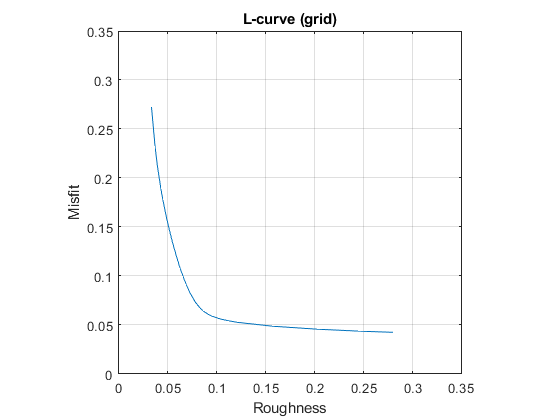

x = Table_Converge(:,3);
y = Table_Converge(:,2);

xf = flip(x); yf = flip(y);

figure()
plot(xf,yf)
grid on
axis equal
axis([0 0.35 0 0.35]) % --> Μεταβάλλω ανάλογα
xlabel('Roughness'); ylabel('Misfit');
title('L-curve (grid)')

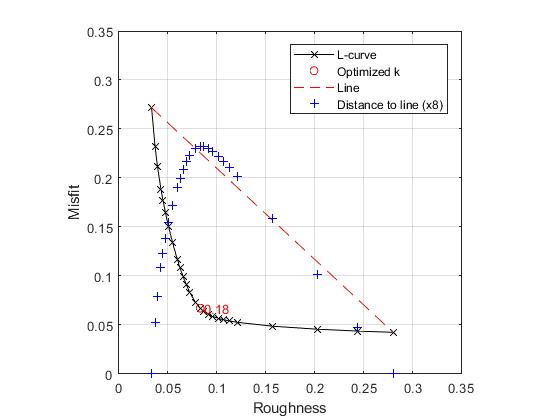


% Συντεταγμένες των σημείων Misfit-Roughness
SF_Coord = [xf yf];

% Πρώτο σημείο
firstPoint = SF_Coord(1,:);

% Το διάνυσμα από το πρώτο ως το τελευταίο σημείο. Αυτή είναι η γραμμή.
lineVec = SF_Coord(end,:) - firstPoint;

% Κανονικοποίηση του διανύσματος (προκύπτει το μοναδιαίο)
lineVecN = lineVec / sqrt(sum(lineVec.^2));

% Εύρεση της απόστασης κάθε σημείου [Roughness, Misfit] από τη γραμμή:
    % 1) Το διάνυσμα για κάθε σημείο [Roughness, Misfit] από το πρώτο σημείο.
    vecFromFirst = bsxfun(@minus, SF_Coord, firstPoint);
    
    % 2) Για να υπολογιστεί η απόσταση από τη γραμμή, σπάμε το 'vecFromFirst' σε
    % δύο διανύσματα (συνιστώσες), ένα παράλληλο και ένα κάθετο στη γραμμή. Η 
    % απόσταση είναι το μέτρο του κάθετου διανύσματος.
    % Βρίσκουμε το διάνυσμα που είναι παράλληλο στη γραμμή προβάλλοντας το 
    % 'vecFromFirst' στη γραμμή. Το κάθετο vector είναι το 
    % 'vecFromFirst' - 'vecFromFirstParallel'.
    % Προβάλλουμε το 'vecFromFirst' υπολογίζοντας το εσωτερικό γινόμενο του διανύσματος
    % 'vecFromFirst' με το μοναδιαίο διάνυσμα της γραμμής 'lineVecN', και προκύπτει το 
    % 'scalarProduct'. Το 'vecFromFirstParallel' προκύπτει από πολλαπλασιασμό του 
    % 'scalarProduct' με το μοναδιάιο διάνυσμα 'lineVecN' της ευθείας.
    scalarProduct = dot(vecFromFirst, repmat(lineVecN,SF_points,1), 2);
    vecFromFirstParallel = scalarProduct * lineVecN;  % Το παράλληλο διάνυσμα
    vecToLine = vecFromFirst - vecFromFirstParallel;  % Το κάθετο διάνυσμα

    % Η απόσταση από τη γραμμή είναι το μέτρο του 'vecToLine' (κάθετο διάνυσμα)
    distToLine = sqrt(sum(vecToLine.^2,2));
    
% Υπολογισμός σημείου max απόστασης - ιδανικού συντελεστή k:
[maxDist,idxOfBestPoint] = max(distToLine);
idxOfBestPoint = SF_points - idxOfBestPoint + 1;

SF_grid = SF_values(idxOfBestPoint);

% Δημιουργία του Πίνακα Table_Converge με τις αποστάσεις:
Table_Converge(:,4) = distToLine;
    
% Σχεδίαση της απόστασης των σημείων [Roughness, Misfit] από τη γραμμή
figure()
p1 = plot(xf,yf,'-xk');
grid on
hold on

p2 = plot(x(idxOfBestPoint),y(idxOfBestPoint),'or');
  
p3 = plot(xf([1 end]),yf([1 end]),'--r');

p4 = scatter(xf,distToLine*2,'+b');

t1 = text(x(idxOfBestPoint),y(idxOfBestPoint),SF_values_names(idxOfBestPoint,:));
t1.Color = 'red';

axis equal
axis([0 0.35 0 0.35]) % --> Μεταβάλλω ανάλογα
xlabel('Roughness'); ylabel('Misfit');
    
legend([p1,p2,p3,p4],{'L-curve','Optimized k','Line',...
    'Distance to line (x8)'});

leg.AutoUpdate = 'off';
leg.Location = 'northeast';

% Αποθήκευση των παραμέτρων
save ('Inv_Par_grid.mat','PR','PS','mR','MR','MS','tD_A','bD_A','tD_B','bD_B','CN','SF_grid','SF_values','SF_values_names')